# Giraffe ADC Testbench 

clear
clc
load("Chip1_102400_LowSpeed.mat");

## AC Low Speed

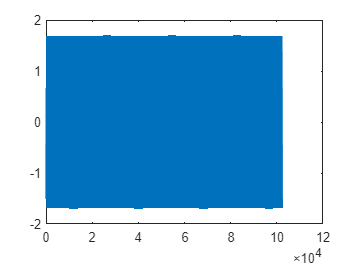

Vref = 1.8;
N_SUB = 5;
LSB_SUB = Vref / 2^N_SUB;

fclock = 50E6 / 1;           % clk_adc = 10kHz;
% fprintf("Number of Sample Points: 64 *  16 tiems average;")
fs = fclock / 25;
N_Sample = length(Vout_N4);

% Vout_N4 = Vout_N4(1:100000, :);
% N_Sample = 100000;
% ~~~~~~~~~~~~~~~ Flash ~~~~~~~~~~~~~~~
figure
plot(Vout_N4(:,1));

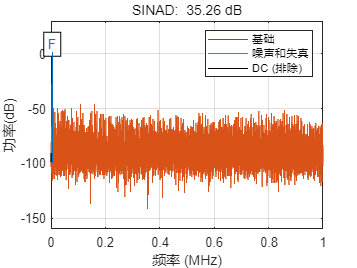

sinad(Vout_N4(:,1), fs);

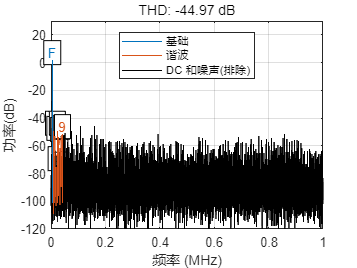

ans = -44.9691

thd(Vout_N4(:,1), fs, 9, "aliased")

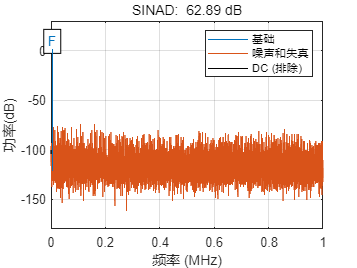

ans = 62.8873

% ~~~~~~~~~~~~~~~ without calibration ~~~~~~~~~~~~~~~
Vout_without_calib = zeros(N_Sample, 1);
for i=1:N_Sample
    Vout_without_calib(i) = Calib_Gain(Vout_N4(i,:), 16);
end
sinad(Vout_without_calib, fs)

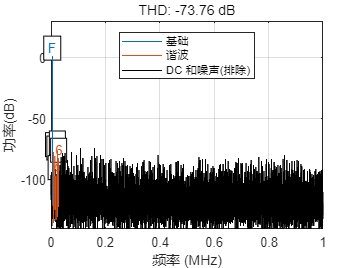

ans = -73.7561

thd(Vout_without_calib, fs, 'aliased')

## Calibration

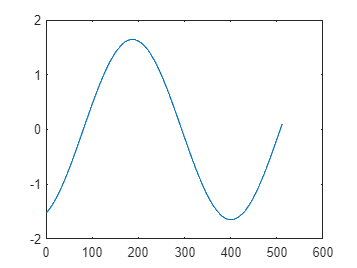

% ~~~~~~~~~~~~~~~ plus calibration ~~~~~~~~~~~~~~~
Vout_plus_calib = zeros(N_Sample, 1);
for i=1:N_Sample
    Vout_plus_calib(i) = Calib_Gain(Vout_N4(i,:), abs(GAIN_PLUS));
end
plot(Vout_plus_calib(1:512,1));

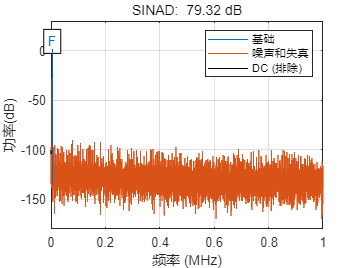

ans = 79.3239

sinad(Vout_plus_calib, fs)

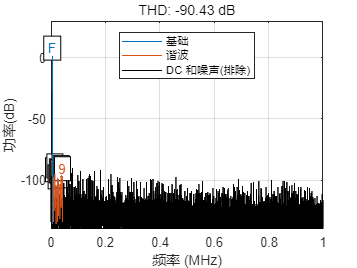

ans = -90.4284

thd(Vout_plus_calib, fs, 9, 'aliased')

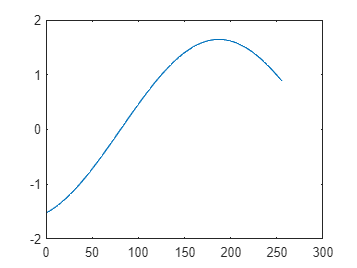



% ~~~~~~~~~~~~~~~ minus calibration ~~~~~~~~~~~~~~~
Vout_minus_calib = zeros(N_Sample, 1);
for i=1:N_Sample
    Vout_minus_calib(i) = Calib_Gain(Vout_N4(i,:), GAIN_MIN);
end
plot(Vout_minus_calib(1:256,1));

V0 = repmat(Vout_minus_calib, [1,1]);
V1 = V0 .* hamming(length(V0));
sinad(V1, fs)

ans = 79.3961

thd(Vout_minus_calib, fs, 9, 'aliased')

% ~~~~~~~~~~~~~~~ mean calibration ~~~~~~~~~~~~~~~
Vout_mean_calib = zeros(N_Sample, 1);
for i=1:N_Sample
    Vout_mean_calib(i) = Calib_Gain(Vout_N4(i,:), mean(abs([GAIN_MIN, GAIN_PLUS])));
%     Vout_mean_calib(i) = Calib_Gain(Vout_N4(i,:), 15.4);
end
plot(Vout_mean_calib(1:256,1));
sinad(Vout_mean_calib, fs)
thd(Vout_mean_calib , fs, 9, 'aliased')
sfdr(Vout_mean_calib, fs)


% w=hamming(N_Sample);
% Vout_windowed = w.*Vout_mean_calib;
% 
% thd(Vout_windowed , fs, 9, 'aliased')
% sinad(Vout_windowed, fs)
LSB = Vref / 2^15;
negetive = Vout_mean_calib < 0;
quan2 = floor(Vout_mean_calib / LSB) + negetive;

Vout_quan = quan2 .* LSB;
sinad(Vout_quan, fs)
thd(Vout_quan , fs, 9, 'aliased')
sfdr(Vout_quan, fs)
 max(Vout_mean_calib)
 min(Vout_mean_calib)   


## Gain Sweep

gain_sweep = 15:0.0001:16;
sinad_sweep = zeros(size(gain_sweep));
thd_sweep = zeros(size(gain_sweep));
parfor j = 1:length(gain_sweep)
    Vout_sweep = zeros(N_Sample, 1);
    for i=1:N_Sample
        Vout_sweep(i) = Calib_Gain(Vout_N4(i,:), gain_sweep(j));
    end
    sinad_sweep(j) = sinad(Vout_sweep, fs);
    thd_sweep(j) = thd(Vout_sweep, fs, 9, 'aliased');
end

max(sinad_sweep)
min(thd_sweep)
sinad_index = find(sinad_sweep == max(sinad_sweep))
thd_index = find(thd_sweep == min(thd_sweep))
gain_sweep(sinad_index)
gain_sweep(thd_index)
figure
yyaxis left
plot(gain_sweep, sinad_sweep);

ylabel("SINAD [dB]")
yyaxis right
plot(gain_sweep ,thd_sweep)
ylabel("THD [dB]")
xlabel("Gain")
grid on



## Gain and offset sweep

gain_sweep = 15:0.01:16;            % gain: [15, 16]
offset_sweep = -0.1:0.001:0.1;    % offet: [-50m, 50m]
len1 = length(gain_sweep);
len2 = length(offset_sweep);

thd_sweep1 = zeros(len1, len2);
sinad_sweep1 = zeros(len1, len2);

for i = 1:len1
    for j = 1:len2
%         Vout_sweep = zeros(N_Sample, 1);
        Vout_sweep = Calib_Gain_offset(Vout_N4, gain_sweep(i), offset_sweep(j));
        sinad_sweep1(i,j) = sinad(Vout_sweep, fs);
        thd_sweep1(i,j) = thd(Vout_sweep, fs, 9, 'aliased');
    end
    fprintf("%d - finished!\n", i);
end


% [X, Y] = meshgrid(gain_sweep, offset_sweep);
% z
figure
mesh(gain_sweep, offset_sweep, thd_sweep1');
xlabel('Gain');
ylabel('Offset [V]')
zlabel('THD [dB]')

figure
mesh(gain_sweep, offset_sweep, sinad_sweep1');
xlabel('Gain');
ylabel('Offset [V]')
zlabel('SINAD [dB]')

V1 = Calib_Gain_offset(Vout_N4, 16, 0.01)
V2 = Calib_Gain_offset(Vout_N4, 16, -0.01)
dV = V1 - V2;
figure
thd(V1, fs, 5);

figure
thd(V2, fs, 5);

subplot(211)
plot(V1)
hold on
plot(V2)
hold off;
xlim([0, 1280])
grid on
xlabel('Sample Points')
legend(["Offset = 10mV"; "Offset = -10mV"]);

subplot(212)
plot(dV)
xlim([0, 1280]);
ylim([0.07999, 0.08001])
grid on
xlabel('Sample Points')
legend(["Delta V"]);

figure
plot(offset_sweep, thd_sweep1(31,:))

xlabel('Offset [V]');
ylabel('THD [dB]');
title("when G = 15.31")

## Noise Analysis

% [f, p, NV_rms] = Noise_PSD(Vout_without_calib, fs);
% figure
% plot(f, 10*log10(p));
% grid on;
% % Periodgram
% 
% periodogram(Vout_without_calib, ...
%         rectwin(N_Sample), N_Sample, fs, 'PSD');
% 
% PsdSectionLength = 2048;
% NumSection = N_Sample / PsdSectionLength;
% PSD = [];
% for i=1:NumSection
%     index_head = (i-1)*PsdSectionLength+1;
%     index_tail = i*PsdSectionLength;
%     [pxx,f ] = periodogram(Vout_without_calib(index_head:index_tail), ...
%         hann(PsdSectionLength), N_Sample, fs, 'PSD');
%     PSD = [PSD,pxx];
% end
% PSD_AVE = mean(PSD,2);
% figure
% plot(f, 10*log10(PSD_AVE));
% xlabel('Frequency [Hz]');
% ylabel('PSD [dB/Hz]')
% grid on
% %integrated Noise
% Noise_RMS = sqrt(sum(PSD_AVE*(fs/(N_Sample))))

% Integrated Noise in Power
Noise_RMS = pow2db(var(Vout_mean_calib))

% Periodgram

[pxx_1, f] = periodogram(Vout_mean_calib, ...
        rectwin(N_Sample), N_Sample, fs, 'PSD');
pxx_1(1)=  0;
pow2db(sum(pxx_1 * (fs/N_Sample)) )
figure
plot(f, 10*log10(pxx_1));
xlabel('Frequency [Hz]');
ylabel('PSD [dB/Hz]')
grid on
title(['Noise Floor: ', num2str(Noise_RMS), ' dB'])
% pxx(1) = 0;
% % pow2db(sum(p1 * (fs/N_Sample)))
% offset = mag2db(mean(Vout_without_calib))

% function serial_callback(src,evt)
%     data = readline(src);
% %     disp(data)
%     src.UserData = data;
% end


function V_calib = Calib_Gain_offset(V_uncalib, GainA, offset)
    V_calib = zeros(length(V_uncalib),1);
%     V_calib = V_uncalib(:,1) +
    for i = 1:4
        V_calib = V_calib + (V_uncalib(:,i) / GainA^(i-1) + offset);
    end    
end
function serial_callback(s, ~)
%     global data_serial;
    data = read(s, 1, 'uint8');
    s.UserData = [s.UserData; data];
    % 通过串口对象自身将读取数据带回；
    disp(data)
end